clear all; close all

%%studying the properties of centrality measurements 
N = 10; %number of node
n = 10; %number of edges
G = generate_layer(N,n) %erdos-renyi graaf

G =   graph with properties:

    Edges: [10×1 table]
    Nodes: [10×0 table]


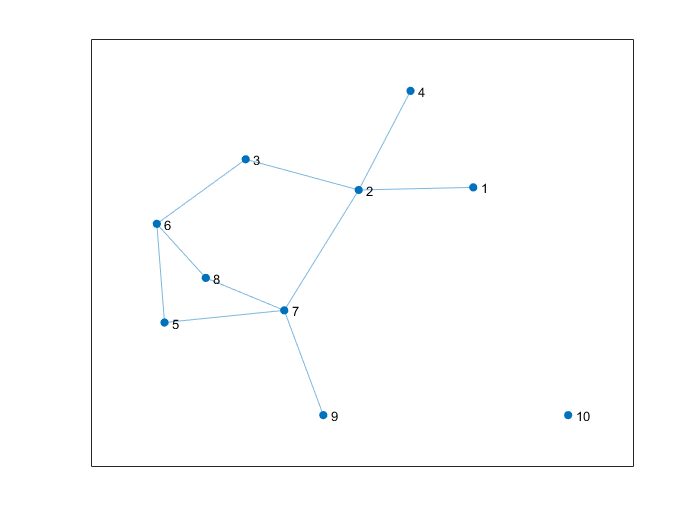

varNames = { 'node','betweenness','closeness','degree', 'pagerank', 'eigenvector'};
l = length(varNames);
varTypes = cell(1,l);
varTypes(1:l) = {'double'};

sz = [N length(varTypes)];
T = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

T.node(1:N) = [1:N];
T.betweenness(1:N) = centrality(G,'betweenness');
T.closeness(1:N) = centrality(G,'closeness');
T.degree(1:N) = centrality(G,'degree');
T.pagerank(1:N) = centrality(G,'pagerank');
T.eigenvector(1:N) = centrality(G,'eigenvector');

plot(G)

sortrows(T,'eigenvector','descend') 

ans = 10×6 table
    node    betweenness    closeness    degree    pagerank    eigenvector
    ____    ___________    _________    ______    ________    ___________

      7        13.5        0.065844       4         0.1871      0.15874  
      2          15        0.065844       4        0.19645      0.14007  
      6         2.5        0.049383       3         0.1391      0.11995  
      5           1        0.049383       2       0.095525      0.10676  
      8           1        0.049383       2       0.095525      0.10676  
     10           0               0       0       0.016393          0.1  
      3           3        0.052675       2       0.097515     0.099605  
      9           0        0.041585       1       0.056139     0.060809  
      1           0        0.041585   

%removing edges to see what happens to the average centrality score
varNames = { 'edge','mean','std','min', 'max'};
l = length(varNames);
varTypes = cell(1,l);
varTypes(1:l) = {'double'};
varTypes(1) = {'string'};
    
sz = [4 length(varTypes)];
D = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

TheVar = 'eigenvector'; %the variable that will be investigated
G_centrality = centrality(G,TheVar); %centrality score of the original system

i = 1; %manual itterable 
r = G.rmedge(2,1);
D.edge(i) = '2-1';
r_centrality = centrality(r,TheVar); %centrality score of the system with a removed edge
D.mean(i) = mean(r_centrality) - mean(G_centrality);
D.std(i) = std(r_centrality) - std(G_centrality);
D.min(i) = min(r_centrality) - min(G_centrality);
D.max(i) = max(r_centrality) - max(G_centrality);

i = 2; %manual itterable 
r = G.rmedge(2,7);
D.edge(i) = '2-7';
r_centrality = centrality(r,TheVar); %centrality score of the system with a removed edge
D.mean(i) = mean(r_centrality) - mean(G_centrality);
D.std(i) = std(r_centrality) - std(G_centrality);
D.min(i) = min(r_centrality) - min(G_centrality);
D.max(i) = max(r_centrality) - max(G_centrality);

i = 3; %manual itterable 
r = G.rmedge(8,7);
D.edge(i) = '8-7';
r_centrality = centrality(r,TheVar); %centrality score of the system with a removed edge
D.mean(i) = mean(r_centrality) - mean(G_centrality);
D.std(i) = std(r_centrality) - std(G_centrality);
D.min(i) = min(r_centrality) - min(G_centrality);
D.max(i) = max(r_centrality) - max(G_centrality)    

D = 4×5 table
      edge          mean           std           min           max    
    _________    ___________    __________    __________    __________

    "2-1"         1.3878e-17    -0.0052836    -0.0088764    -0.0057912
    "2-7"        -1.3878e-17      0.012327     -0.021154     0.0075669
    "8-7"         1.3878e-17     0.0025093    -0.0051711     0.0096391
    <missing>              0             0             0             0
